Ejercicio 1


$$\begin{array}{l}
R=100\;\Omega \\
C=0\ldotp 22\;\mu F\\
L=2\ldotp 2\;\mathrm{mH}
\end{array}$$
   

R = 100;             % Resistencia en ohmios
C = 0.22e-6;         % Capacitancia en microfaradios
L = 2.2e-3;          % Inductancia en milihenrios

% Cálculo de la frecuencia natural y el factor de amortiguamiento
Wn = 1/(sqrt(L*C))            % Frecuencia natural

Wn = 4.5455e+04

Xi = (R*sqrt(C))/(2*sqrt(L))  % Factor de amortiguamiento

Xi = 0.5000


%Sobrepaso máximo (Mp)
Mp = 100*exp(-(Xi*pi)/(sqrt(1-(Xi^2))))

Mp = 16.3034


%Tiempo de asentamiento o establecimiento (Ts)
Ts2 = 4/(Xi*Wn)

Ts2 = 1.7600e-04

Ts5 = 3/(Xi*Wn)

Ts5 = 1.3200e-04


%Tiempo de levantamiento (Tr) y Tiempo de retardo (Td)
Theta = atan((sqrt(1-(Xi^2)))/(Xi))

Theta = 1.0472

Wd = Wn*(sqrt(1-(Xi^2)))

Wd = 3.9365e+04

Tr = (pi-Theta)/(Wd)

Tr = 5.3205e-05

Td = Tr/2

Td = 2.6602e-05


%Tiempo pico (Tp)
Tp = (pi)/(Wd)

Tp = 7.9807e-05


num = [Wn^2];
den = [1 2*Xi*Wn Wn^2];
G = tf(num,den)

G =
 
           2.066e09
  ---------------------------
  s^2 + 4.545e04 s + 2.066e09
 
Continuous-time transfer function.
Model Properties


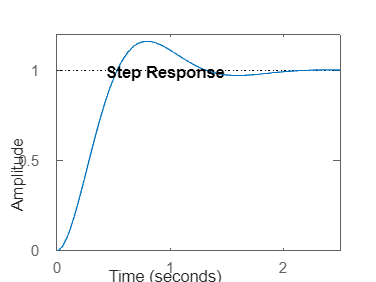

step(G)

Ejercicio 2